# Solución de la ecuación de Schrödinger no lineal acoplada por el método de Galerkin: Un caso de estudio

Este notebook tiene como propósito implementar y analizar el esquema de elementos finitos de Galerkin para la ESNL acoplada, reproduciendo los distintos escenarios numéricos de propagación de solitones e interacciones no lineales descritos en el informe. Para cada conjunto de parámetros, la función `NLS `resuelve el problema inicial con condiciones de frontera y genera la aproximación numérica $U(x_m,t_n)$; a partir de estas soluciones, la rutina `NLS_INVARIANTS` calcula las cantidades conservadas $I_1, \ I_2, \ I_3 \ y \ I_4$ mediante cuadratura numérica, que luego se emplean para evaluar la precisión y la capacidad de conservación del método. Adicionalmente se incluyen de manera comentada cómo gráficar las soluciones para cada caso.

Se ejecutan exactamente los mismos escenarios numéricos que fueron presentados en el informe, siguiendo la misma estructura y parametrización. El primer escenario corresponde a la propagación de **un único solitón**, seguido por el segundo escenario que estudia la **interacción de tres ondas tipo solitón** y por ultimo se realizaron distintos casos de la **interacción no lineal de dos solitones variando las condiciones inicales**. Los casos construidos a partir de interacciones de dos solitones, son: **SIstema de Manakov**,** Fusión**, **Transmisión**, **Creación** y **Reflexión**, todos configurados con sus parámetros específicos y perfiles iniciales correspondientes.

**Nota**: Para la reproducibilidad de los resultados presentados en el documento de investigación, es **necesario** realzar la ejecución de los escenarios y casos presentes **excluyendo** unicamente la presición del esquema númerico.

# Parámetros comunes

Se definen algunos de los parámetros que se usaron para realizar las simulaciones los cuales son los mismos para cada escenario realizado. Para cada ejecución se uso un $h=0.001, \ k=0.01, \ x_L=-20, \ x_R=60 $ y el método de Newton se le estableció una tolerancia $\varepsilon = 1 \times 10^{-10}$. El tiempo final varia según el escenario y el caso.

clear all;
Nx = 8001; k = 1e-2; xL = -20; xR = 60; tolNewton = 1e-10; saveEvery = 1;

## Única onda tipo solitón

Se presenta la simulación de un único solitón y describe cómo se implementa su propagación en el dominio y el espacio, especificando las condiciones iniciales, los parámetros utilizados y la forma en que se obtiene la solución numérica para este caso base. Además, se calculas las cantidad $I_1, \ I_3  \ y \ I_4$ y el error entre la primera cantidad conservada de forma númerica con su solución exacta $I_1  = \frac{2}{1 + e} \sqrt{2\alpha}. $

Las condiciones inciales son: 


$$ \Psi_1(x, 0) = \Psi_2(x, 0) =\sqrt{\frac{2\alpha}{1 + e}} \sech(\sqrt{2\alpha} x) \exp {i v x}$$


donde 


$$\quad v = 1.0, \quad \alpha = 1.0, \quad e = 1.$$$


%Cálculo de la solución para el caso de un solitón  
alphaA = 1; ee = 1; vv = 1; Tfinal = 40;
psi_exact = @(x,t) sqrt(2*alphaA/(1+ee)).*sech( sqrt(2*alphaA)*(x - vv.*t) ) ...
                   .*exp( 1i*( vv*x - (0.5*vv^2 - alphaA)*t ) );
IC = @(x) [psi_exact(x,0); psi_exact(x,0)];
psi_exact_full = @(x,t) [psi_exact(x,t); psi_exact(x,t)];

% Cálculo de la solución
[U, x, t, stats] = nls(alphaA,ee,vv,Tfinal,IC, ...
    'Nx',Nx,'k',k,'xL',xL,'xR',xR,'saveEvery',saveEvery, ...
    'ExactSolution',psi_exact_full);

% Descomposición de las componentes en las soluciones individuales del sistema 
U1_num = U(1:length(x), :);
U2_num = U(length(x)+1:end, :);

% Cálculo de la conservación de cantidades y comparación
cons = nls_invariants(x, U, t, 'e', 1, 'alpha', 1.0, 'PaperStep', 10);


  CANTIDADES CONSERVADAS
  Coeficiente de acoplamiento e = 1.0000
  Valor analítico I1 = 1.414214  (solitón simple, alpha = 1.00)
--------------------------------------------------------
  Time      I1          I2          I3          I4
--------------------------------------------------------
   0.00    1.414214    1.414214   -5.545539    0.347460
  10.00    1.414214    1.414214   -5.552434    0.363610
  20.00    1.414214    1.414214   -5.550246    0.360977
  30.00    1.414214    1.414214   -5.548896    0.362018
  40.00    1.414214    1.414214   -5.547526    0.361925

  ERRORES RELATIVOS MÁXIMOS
  I1: 7.251e-13
  I2: 7.232e-13
  I3: 1.594e-03
  I4: 5.830e-02

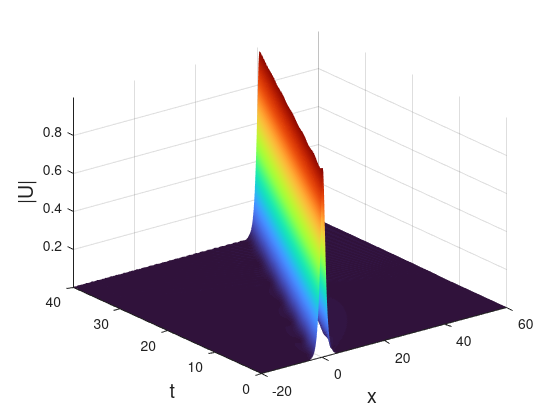


% Graficar en 3D
[X,T] = meshgrid(x,t);
figure;
surf(X,T,abs((U1_num)'))  
shading interp
colormap(turbo)
axis tight
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)
zlabel('|U|', 'FontSize',14)

## Precisión del esquema númerico

Se demostró en el documento de investigación que el esquema propuesto es de segundo orden en espacio y tiempo, es consistente ya que el error de truncamiento local $${T}_{m}^n = O(h^2)+O(k^2)$$ tiende a cero cuando $$h$ $y $$k$ $se aproximan a cero. De acuerdo con el teorema de Lax, el esquema propuesto es convergente ya que es consistente e incondicionalmente estable. Por lo que, se relizó una simulación para la verificación de la preción del esquema númerico.

#### Convergencia en el espacio

Para probar si el esquema numérico propuesto exhibe la tasa de convergencia esperada en el espacio, se realizaron experimentos numéricos para diferentes valores de $$h$ $con un tiempo fijo $$t = 4$$ y $ $k = 0.01$$ para asegurar que el error temporal es despreciable.

conv_table = convergencia_espacial();

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
✓ Pool paralelo creado

Calculando convergencia espacial EN PARALELO...
═══════════════════════════════════════
Parámetros 
Tolerancia Newton: 1e-08
Ejecutando 4 simulaciones en paralelo...

[Worker] Malla h = 0.0250, Δt = 0.000063, Nx = 3200 - INICIANDO...
[Worker] Malla h = 0.0500, Δt = 0.000250, Nx = 1600 - INICIANDO...
[Worker] Malla h = 0.1000, Δt = 0.001000, Nx = 800 - INICIANDO...
[Worker] Malla h = 0.2000, Δt = 0.004000, Nx = 400 - INICIANDO...
[Worker] Malla h = 0.2000 - COMPLETADA. Error L∞ = 1.475669e-01
[Worker] Malla h = 0.1000 - COMPLETADA. Error L∞ = 3.861701e-02
[Worker] Malla h = 0.0500 - COMPLETADA. Error L∞ = 9.778215e-03
[Worker] Malla h = 0.0250 - COMPLETADA. Error L∞ = 2.451815e-03

✓ Todas las simulaciones completadas

═══════════════════════════════════════
TABLA DE CONVERGENCIA ESPACIAL
═══════════════════════════════════════

      h  

#### Convergencia en tiempo

De forma analoga, se busca ver la tasa de convergencia esperada en el tiempo, se realizaron experimentos numericos para diferentes valores de $k
$ con un tiempo fijo $t=4$ y un $h=0.001$ para asegurar que el error en el espacio sea despreciable.

conv_table_temporal = convergencia_temporal();

✓ Pool paralelo ya activo

Calculando convergencia temporal EN PARALELO...
═══════════════════════════════════════
Parámetros 
Tolerancia Newton: 1e-12
Espaciado espacial fijo: h = 0.0010
Ejecutando 4 simulaciones en paralelo...

[Worker] Paso de tiempo Δt = 0.0500, h = 0.0010, Nx = 80000 - INICIANDO...
[Worker] Paso de tiempo Δt = 0.1000, h = 0.0010, Nx = 80000 - INICIANDO...
[Worker] Paso de tiempo Δt = 0.2000, h = 0.0010, Nx = 80000 - INICIANDO...
[Worker] Paso de tiempo Δt = 0.0250, h = 0.0010, Nx = 80000 - INICIANDO...
[Worker] Paso de tiempo Δt = 0.2000 - COMPLETADA. Error L∞ = 1.095925e-01
[Worker] Paso de tiempo Δt = 0.1000 - COMPLETADA. Error L∞ = 2.882611e-02
[Worker] Paso de tiempo Δt = 0.0500 - COMPLETADA. Error L∞ = 7.305065e-03
[Worker] Paso de tiempo Δt = 0.0250 - COMPLETADA. Error L∞ = 1.835260e-03

✓ Todas las simulaciones completadas

═══════════════════════════════════════
TABLA DE CONVERGENCIA TEMPORAL
═══════════════════════════════════════

    Delta_t

## Interacción de tres ondas tipo solitón (solitones vectoriales)

En el caso de **tres solitones**, se especifican los parámetros y las condiciones iniciales de cada componente, se ejecuta la simulación completa, se obtienen las cantidades conservadas. Además, se calculas las cantidad $I_1, \ I_3  \ y \ I_4$ y el error entre la primera cantidad conservada de forma númerica con su solución exacta $ I_1 = \frac{2}{1+e} \sum_{j=1}^3 \sqrt{2\alpha_j}.$

Las condiciones inicales son: 


$$    \Psi_1(x, 0) =  \Psi_2(x, 0)= \sum_{j=1}^3 \sqrt{\frac{2\alpha_j}{1+e}} \, \sech(\sqrt{2\alpha_j}(x-x_j)) \, \exp i\{x v_j\}$$


donde 


$$x_1 = 0, \quad x_2 = 25, \quad x_3 = 50,  \quad
v_1 = 1.0, \quad v_2 = 0.1, \quad v_3 = -1.0, \alpha_1 = 1, \quad \alpha_2 = 0.6, \quad \alpha_3 = 0.3, \ y \ e = 2/3$$$


%Simulación de tres solitones
ee = 2/3; vv = 0; Tfinal = 40;
a1=1.0; a2=0.6; a3=0.3; v1=1.0; v2=0.1; v3=-1.0; x1=0; x2=25; x3=50;
P3 = @(x) sqrt(2*a1/(1+ee)).*sech(sqrt(2*a1)*(x - x1)).*exp(1i*v1*x) ...
        + sqrt(2*a2/(1+ee)).*sech(sqrt(2*a2)*(x - x2)).*exp(1i*v2*x) ...
        + sqrt(2*a3/(1+ee)).*sech(sqrt(2*a3)*(x - x3)).*exp(1i*v3*x);

IC = @(x) [P3(x(:)); P3(x(:))];   % Condición inicial

% Cálculo de la solución
[U3, x, t3, S3] = nls(a1,ee,vv,Tfinal,IC, ...
    'Nx',Nx,'k',k,'xL',xL,'xR',xR,'saveEvery',saveEvery);

% Descomposición de las componentes en las soluciones individuales del sistema 
U31_num = U3(1:length(x), :);
U32_num = U3(length(x)+1:end, :);

% Cálculo de la conservación de cantidades y comparación
cons = nls_invariants(x, U3, t3, 'e', 2/3, 'alpha', [1.0, 0.6, 0.3], 'PaperStep', 10);


  CANTIDADES CONSERVADAS========================================================
  Coeficiente de acoplamiento e = 0.6667
  Valor analítico I1 = 3.941106  (suma de 3 solitones)
  Alphas: [1.00 0.60 0.30 ]
--------------------------------------------------------
  Time      I1          I2          I3          I4
--------------------------------------------------------
   0.00    3.941106    3.941106   -3.497474    0.607238
  10.00    3.941106    3.941106   -3.504636    0.628619
  20.00    3.941106    3.941106   -3.532821    0.568304
  30.00    3.941106    3.941106   -3.501467    0.627132
  40.00    3.941106    3.941106   -3.500662    0.629316

  ERRORES RELATIVOS MÁXIMOS
  I1: 1.772e-13
  I2: 1.768e-13
  I3: 2.862e-02
  I4: 5.309e-01

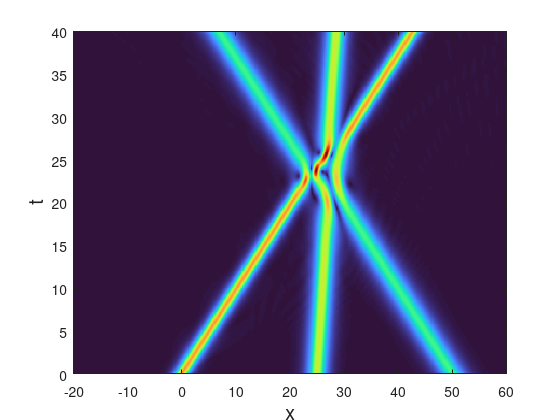


% Gráficas de la solución obtenida

% Gráfica 2D
imagesc(x, t3, abs(U31_num).');
axis xy;
colormap(turbo);
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)

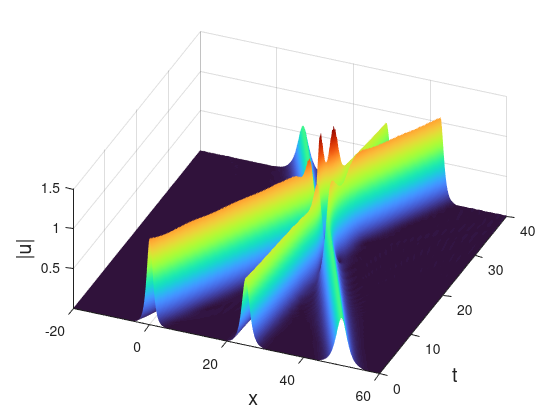


% Gráfica 3D
[X,T3] = meshgrid(x,t3);
figure; 
surf(X,T3,abs((U31_num)'))                
shading interp
colormap(turbo)
axis tight
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)
zlabel('|u|', 'FontSize',14)
[az,~] = view;
view(az+60,55)

# Colisiones de ondas tipo solitón con diferentes condiciones iniciales

Sean las condiciones iniciales: 


$$\Psi_1(x, 0) = \sqrt{2\alpha_1} \, \text{sech}(\sqrt{2\alpha_1}x + x_0) \, \exp(iv_1 x), \quad \Psi_2(x, 0) = \sqrt{2\alpha_2} \, \text{sech}(\sqrt{2\alpha_2}x - x_0) \, \exp(iv_2 x),$$


donde las amplitudes $\sqrt{2\alpha_j}$, velocidades $v_j
$ y constante de fase inicial $x_0$ con $$v_1 = v/2$$ y $$v_2=-v_1$.
$ Así que la velocidad de aproximación de los dos solitones es $$v$$. También fijamos $$\alpha_1 = 1.2$$ y $$\alpha_2 = 1$$. Las elecciones para el parámetro de posición inicial $$x_0$$ pueden ser totalmente arbitrarias, ya que, no afectarán el resultado de la colisión siempre que $$x_0$$sea lo suficientemente grande. Por tanto, se fijo $ $x_0 = 10$$ en nuestros cálculos. Los únicos parámetros libres que quedan son el coeficiente de modulación de fase cruzada $e
$, y la velocidad de colisión $v$, que se utilizarán como parámetros de control. El tiempo final varia entre cada simulación.

## Interacción de dos ondas (sistema de Manakov)

Para la simulación se tomaron los valores libres $$e=1$$ y $$v=0.4$ $con un tiempo final $$t=60.$$ Vease que, particularmente, cuando el coeficiente de modulación cruzada $$e=1$ $se le conocé como sistema de Manakov. Adicionalmente, se cálculan las cantidad $I_1, \ I_2 \ I_3 \ y \ I_4.$

ee = 1.0;      % Integrable → colisión elástica
v = 0.4;       % Baja velocidad
x0 = 10;
a1 = 1.2;
a2 = 1.0;
Tfinal=60;

% Condición inicial
IC = @(x) [ sqrt(2*a1) * sech(sqrt(2*a1)*(x + x0)) .* exp(1i*v/2*(x + x0));
            sqrt(2*a2) * sech(sqrt(2*a2)*(x - x0)) .* exp(-1i*v/2*(x - x0)) ];

% Cálculo de la solución
[Uc, x, tc, Sc] = nls(a1,ee,0,Tfinal,IC, ...
    'Nx',Nx,'k',k,'xL',xL,'xR',xR,'saveEvery',saveEvery);

% Descomposición de las componentes en las soluciones individuales del sistema 
Uc1_num = Uc(1:length(x), :);
Uc2_num = Uc(length(x)+1:end, :);

% Conservación de cantidad
cons = nls_invariants(x, Uc, tc, 'e', 1, 'alpha', [1.2, 1.0], 'PaperStep', 10);


  CANTIDADES CONSERVADAS========================================================
  Coeficiente de acoplamiento e = 1.0000
  Valor analítico I1 = 2.963407  (suma de 2 solitones)
  Alphas: [1.20 1.00 ]
--------------------------------------------------------
  Time      I1          I2          I3          I4
--------------------------------------------------------
   0.00    3.098387    2.828427   -0.103315   -2.157347
  10.00    3.098387    2.828427   -0.103929   -2.146099
  20.00    3.098387    2.828427   -0.104317   -2.145888
  30.00    3.098387    2.828427   -0.104421   -2.144726
  40.00    3.098387    2.828427   -0.104082   -2.144521
  50.00    3.098387    2.828427   -0.104042   -2.144084
  60.00    3.098387    2.828427   -0.103505   -2.145622

  ERRORES RELATIVOS MÁXIMOS

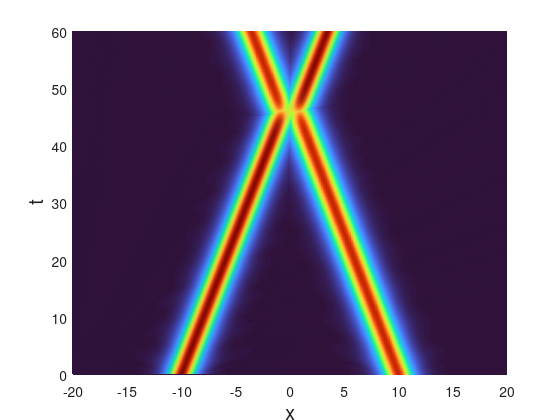


% Gráficas 2D vista desde arriba
[X,Tc] = meshgrid(x,tc);
fig = figure('Renderer','painters');
surf(X,Tc,abs((Uc1_num)'),'EdgeColor','none', 'FaceAlpha', 0.95) 
hold on
mesh(X,Tc,abs((Uc2_num)'), 'EdgeColor','k')
hold off               
shading interp
colormap(turbo)
axis tight
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)
zlabel('|U|','FontSize',14)
[az,~] = view;
view(az+30,75)
xlim([-20,20])
view(2)
axis xy

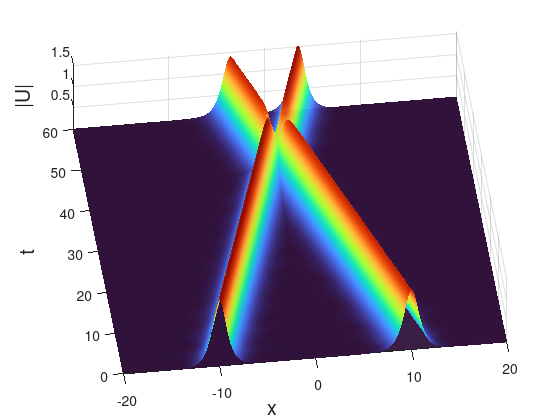

drawnow

% Gráficas 3D
[X,Tc] = meshgrid(x,tc);
fig = figure('Renderer','painters');
surf(X,Tc,abs((Uc1_num)'),'EdgeColor','none', 'FaceAlpha', 0.95) 
hold on
mesh(X,Tc,abs((Uc2_num)'), 'EdgeColor','k')
hold off               
shading interp
colormap(turbo)
axis tight
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)
zlabel('|U|','FontSize',14)
[az,~] = view;
view(az+30,75)
xlim([-20,20])
axis xy

drawnow

## Reflexión de dos ondas tipo solitón

En la simulación se usaron los parámetros libres $$e=2$$ y $$v=0.4$ $con un tiempo final $$t=60.$$

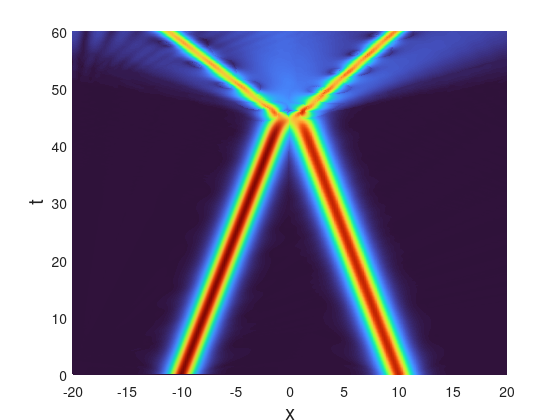

ee = 2.0;      % Alto acoplamiento
v = 0.4;       % Baja velocidad → reflexión
x0 = 10;
a1 = 1.2;
a2 = 1.0;
Tfinal=60;

% Condición inicial
IC = @(x) [ sqrt(2*a1) * sech(sqrt(2*a1)*(x + x0)) .* exp(1i*v/2*(x + x0));
            sqrt(2*a2) * sech(sqrt(2*a2)*(x - x0)) .* exp(-1i*v/2*(x - x0)) ];

[Ur, x, tr, Sr] = nls(a1,ee,v,Tfinal,IC, ...
    'Nx',Nx,'k',k,'xL',xL,'xR',xR,'saveEvery',saveEvery);

% Descomposición de las componentes en las soluciones individuales del sistema 
Ur1_num = Ur(1:length(x), :);
Ur2_num = Ur(length(x)+1:end, :);

% Gráfica 2D desde arriba
[X,Tr] = meshgrid(x,tr);
fig = figure('Renderer','painters');
surf(X,Tr,abs((Ur1_num)'),'EdgeColor','none', 'FaceAlpha', 0.95) 
hold on
mesh(X,Tr,abs((Ur2_num)'), 'EdgeColor','k')
hold off               
shading interp
colormap(turbo)
axis tight
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)
zlabel('|U|','FontSize',14)
[az,~] = view;
view(az+30,75)
xlim([-20,20])
axis xy
drawnow
view(2)

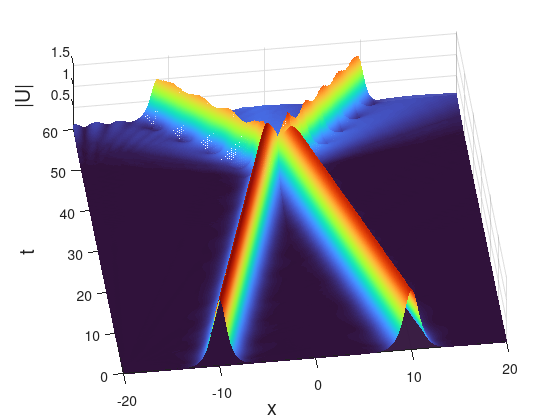


% Gráfica 3D
[X,Tr] = meshgrid(x,tr);
fig = figure('Renderer','painters');
surf(X,Tr,abs((Ur1_num)'),'EdgeColor','none', 'FaceAlpha', 0.95) 
hold on
mesh(X,Tr,abs((Ur2_num)'), 'EdgeColor','k')
hold off               
shading interp
colormap(turbo)
axis tight
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)
zlabel('|U|','FontSize',14)
[az,~] = view;
view(az+30,75)
xlim([-20,20])
axis xy

drawnow

## Transmisión de ondas tipo solitón

Para la simulación se escogieron los valores libres $$e=2/3$ $y $$v=1.6$ $ con tiempo final $$t=40.$$ Se presenta el comportamiento individual de las soluciones numéricas $$\psi_1$ $y $$\psi_2$ $ para visualizar el comportamiento de fibras ópticas con birrefringencia lineal que se consigue cuando el coeficiente de modulación cruzada $ $e=2/3.$$

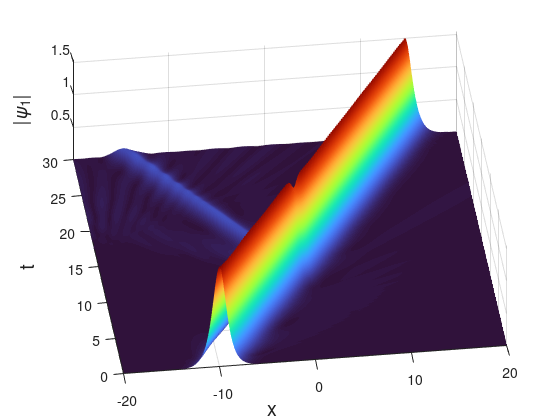

ee = 2/3;      % Fibras birrefringentes lineales
v = 1.6;       % Velocidad de colisión
Tfinal = 40;
x0 = 10;       % Separación inicial
a1 = 1.2;
a2 = 1.0;
v1 = +v/2;     % = 0.8
v2 = -v/2;     % = -0.8

% CONDICIÓN INICIAL 
IC = @(x) [ sqrt(2*a1) * sech(sqrt(2*a1)*(x + x0)) .* exp(1i*v1*(x + x0));   % Ψ₁: solitón izquierda
            sqrt(2*a2) * sech(sqrt(2*a2)*(x - x0)) .* exp(1i*v2*(x - x0)) ]; % Ψ₂: solitón derecha
[Ut, x, tt, St] = nls(a1,ee,v,Tfinal,IC, ...
    'Nx',Nx,'k',k,'xL',xL,'xR',xR,'saveEvery',saveEvery);

% Descomposición de las componentes en las soluciones individuales del sistema 
Ut1_num = Ut(1:length(x), :);
Ut2_num = Ut(length(x)+1:end, :);

% Gráficas de la solución obtenida \psi_1
[X,Tt] = meshgrid(x,tt);
figure;
surf(X,Tt,abs((Ut1_num)'))              
shading interp
colormap(turbo)
axis tight
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)
zlabel('|\psi_1|', 'FontSize',14)
[az,~] = view;
view(az+30,65)
xlim([-20,20])
ylim([0,30])

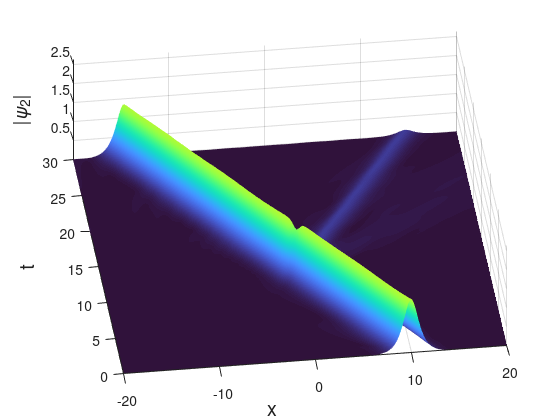


% Gráficas de la solución obtenida \psi_2
[X,Tt] = meshgrid(x,tt);
figure;
surf(X,Tt,abs((Ut2_num)'))              
shading interp
colormap(turbo)
axis tight
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)
zlabel('|\psi_2|', 'FontSize',14)
[az,~] = view;
view(az+30,65)
xlim([-20,20])
ylim([0,30])

## Fusión de ondas tipo solitón

Se realizó la simulación con los valores $$e=0.3$ 
$ y $$v=0.4$ $con un tiempo final $$t=60.$$ Se observa la fusión de solitones dada por la solución numérica $$U(x_m,t_n)$$ dando como resultado un único solitón compuesto de dos ondas.

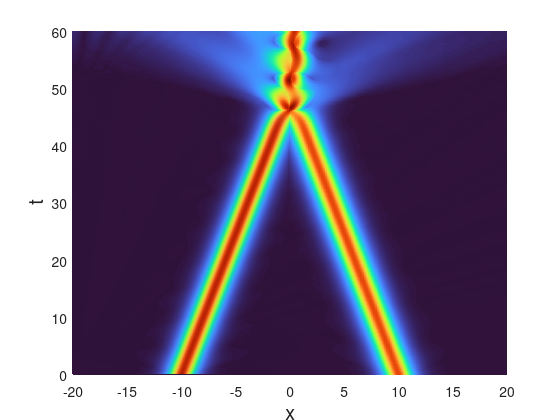

ee = 0.3;      % Bajo acoplamiento
v = 0.4;       % Baja velocidad
x0 = 10;
a1 = 1.2;
a2 = 1.0;
Tfinal = 60;

IC = @(x) [ sqrt(2*a1) * sech(sqrt(2*a1)*(x + x0)) .* exp(1i*v/2*(x + x0));
            sqrt(2*a2) * sech(sqrt(2*a2)*(x - x0)) .* exp(-1i*v/2*(x - x0)) ];
[Uf, x, tf, Sf] = nls(a1,ee,v,Tfinal,IC, ...
    'Nx',Nx,'k',k,'xL',xL,'xR',xR,'saveEvery',saveEvery);

% Descomposición de las componentes en las soluciones individuales del sistema 
Uf1_num = Uf(1:length(x), :);
Uf2_num = Uf(length(x)+1:end, :);

% Gráfica 2D desde arriba
[X,Tf] = meshgrid(x,tf);
fig = figure('Renderer','painters');
surf(X,Tf,abs((Uf1_num)'),'EdgeColor','none', 'FaceAlpha', 0.95) 
hold on
mesh(X,Tf,abs((Uf2_num)'), 'EdgeColor','k')
hold off               
shading interp
colormap(turbo)
axis tight
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)
zlabel('|U|','FontSize',14)
[az,~] = view;
view(az+30,75)
xlim([-20,20])
axis xy
drawnow
view(2)

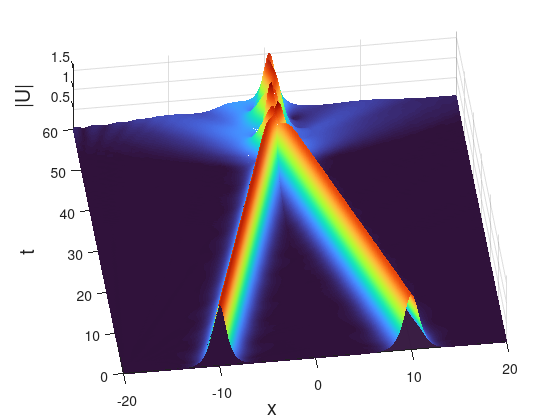


% Gráfica 3D
[X,Tf] = meshgrid(x,tf);
fig = figure('Renderer','painters');
surf(X,Tf,abs((Uf1_num)'),'EdgeColor','none', 'FaceAlpha', 0.95) 
hold on
mesh(X,Tf,abs((Uf2_num)'), 'EdgeColor','k')
hold off               
shading interp
colormap(turbo)
axis tight
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)
zlabel('|U|','FontSize',14)
[az,~] = view;
view(az+30,75)
xlim([-20,20])
axis xy

drawnow

## Creación de la interacción de ondas tipo solitón

Para la simulación se usaron los parámetros $$e=2$$ y $$v=0.8$$ con tiempo final $$t=40.$$ Se analizan la creación de solitones para las componentes de la solución numérica $$\psi_1$$ y $$\psi_2$$ a lo largo del tiempo.

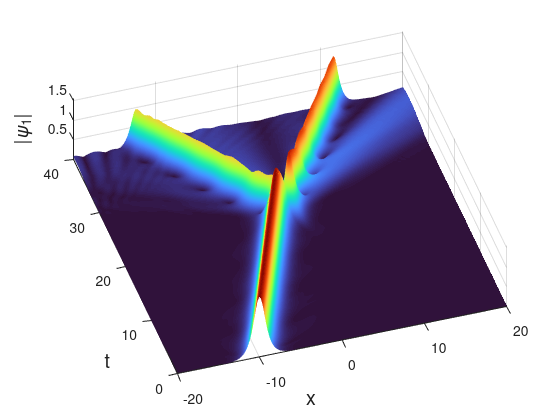

ee = 2.0;      % Alto acoplamiento
v = 0.8;       % Velocidad intermedia
x0 = 10;
a1 = 1.2;
a2 = 1.0;
Tfinal = 40;

% Condición inicial
IC = @(x) [ sqrt(2*a1) * sech(sqrt(2*a1)*(x + x0)) .* exp(1i*v/2*(x + x0));
            sqrt(2*a2) * sech(sqrt(2*a2)*(x - x0)) .* exp(-1i*v/2*(x - x0)) ];

[Un, x, tn, Sn] = nls(a1,ee,v,Tfinal,IC, ...
    'Nx',Nx,'k',k,'xL',xL,'xR',xR,'saveEvery',saveEvery);

% Descomposición de las componentes en las soluciones individuales del sistema 
Un1_num = Un(1:length(x), :);
Un2_num = Un(length(x)+1:end, :);

% Gráficas de la solución obtenida \psi_1
[X,Tn] = meshgrid(x,tn);
figure;
surf(X,Tn,abs((Un1_num)'))              
shading interp
colormap(turbo)
axis tight
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)
zlabel('|\psi_1|', 'FontSize',14)
[az,~] = view;
view(az+20,75)
xlim([-20,20])

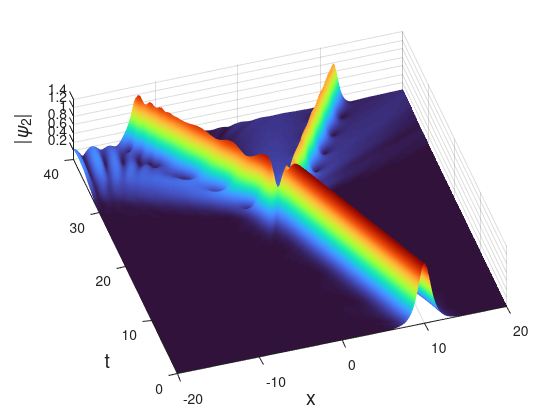


% Gráficas de la solución obtenida \psi_2
[X,Tn] = meshgrid(x,tn);
figure;
surf(X,Tn,abs((Un2_num)'))              
shading interp
colormap(turbo)
axis tight
xlabel('x', 'FontSize',14)
ylabel('t', 'FontSize',14)
zlabel('|\psi_2|', 'FontSize',14)
[az,~] = view;
view(az+20,75)
xlim([-20,20])